%Lab 1: Q1
%1.1

x = [0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14]

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14


y =  [2.56, 1.14, 4.01, 6.02, 4.62, 7.48, 7.79, 9.40, 10.43, 9.23, 13.22, 13.94, 14.30, 15.32, 14.97]

y =     2.5600    1.1400    4.0100    6.0200    4.6200    7.4800    7.7900    9.4000   10.4300    9.2300   13.2200   13.9400   14.3000   15.3200   14.9700


m_x = mean(x)

m_x = 7

m_y = mean(y)

m_y = 8.9620

x = arrayfun(@(x) x-m_x, x)

x =     -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7


y = arrayfun(@(y) y-m_y, y)

y =    -6.4020   -7.8220   -4.9520   -2.9420   -4.3420   -1.4820   -1.1720    0.4380    1.4680    0.2680    4.2580    4.9780    5.3380    6.3580    6.0080


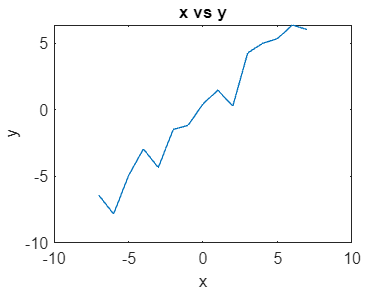

plot(x,y)
xlabel("x")
ylabel("y")
title("x vs y")

cov_matrix = cov(x, y)

cov_matrix =    20.0000   20.5014
   20.5014   22.0081


% In a covarience matrix, we know that the dioganal elements represent the
% varience of each feature and the off-diagonal elements represent the
% covarince of each feature
% In our case, since all the elemnets of the matrix are positive, all the
% features tend to increase or decrease together (i.e. if one feature
% increases so do the others, and if one feature decreases so does the
% other one


[e_vec, e_val] = eig(cov_matrix)

e_vec =    -0.7242    0.6896
    0.6896    0.7242


e_val =     0.4781         0
         0   41.5301



%e_vec is the matrix that represents the eigenvector
%and e_val is a matrix that represents the eigenvalues

[~, max_index] = max(diag(e_val)) % find the index of the maximum eigenvalue

max_index = 2

max_eigenvec = e_vec(:, max_index) % extract the corresponding eigenvector

max_eigenvec =     0.6896
    0.7242




%%1.5



% Generate 100 random x and y coordinates between -10 and 10
rand_x = rand(1, 100)

rand_x =     0.6443    0.3786    0.8116    0.5328    0.3507    0.9390    0.8759    0.5502    0.6225    0.5870    0.2077    0.3012    0.4709    0.2305    0.8443    0.1948    0.2259    0.1707    0.2277    0.4357    0.3111    0.9234    0.4302    0.1848    0.9049    0.9797    0.4389    0.1111    0.2581    0.4087    0.5949    0.2622    0.6028    0.7112    0.2217    0.1174    0.2967    0.3188    0.4242    0.5079    0.0855    0.2625    0.8010    0.0292    0.9289    0.7303    0.4886    0.5785    0.2373    0.4588


rand_y = rand(1, 100)

rand_y =     0.0596    0.6820    0.0424    0.0714    0.5216    0.0967    0.8181    0.8175    0.7224    0.1499    0.6596    0.5186    0.9730    0.6490    0.8003    0.4538    0.4324    0.8253    0.0835    0.1332    0.1734    0.3909    0.8314    0.8034    0.0605    0.3993    0.5269    0.4168    0.6569    0.6280    0.2920    0.4317    0.0155    0.9841    0.1672    0.1062    0.3724    0.1981    0.4897    0.3395    0.9516    0.9203    0.0527    0.7379    0.2691    0.4228    0.5479    0.9427    0.4177    0.9831


m_rx = mean(rand_x)

m_rx = 0.5044

m_ry = mean(rand_y)

m_ry = 0.4783

r_x = arrayfun(@(rand_x) rand_x-m_rx, rand_x)

r_x =     0.1399   -0.1258    0.3071    0.0284   -0.1537    0.4346    0.3715    0.0457    0.1180    0.0826   -0.2967   -0.2032   -0.0335   -0.2740    0.3399   -0.3097   -0.2785   -0.3337   -0.2768   -0.0687   -0.1933    0.4189   -0.0742   -0.3196    0.4004    0.4753   -0.0656   -0.3933   -0.2464   -0.0957    0.0905   -0.2422    0.0984    0.2068   -0.2827   -0.3870   -0.2078   -0.1857   -0.0803    0.0034   -0.4189   -0.2420    0.2966   -0.4752    0.4244    0.2259   -0.0158    0.0741   -0.2672   -0.0456


r_y = arrayfun(@(rand_y) rand_y-m_ry, rand_y)

r_y =    -0.4187    0.2037   -0.4359   -0.4069    0.0433   -0.3816    0.3398    0.3392    0.2441   -0.3284    0.1813    0.0403    0.4947    0.1707    0.3220   -0.0245   -0.0459    0.3470   -0.3948   -0.3451   -0.3049   -0.0874    0.3531    0.3251   -0.4178   -0.0790    0.0486   -0.0615    0.1786    0.1497   -0.1863   -0.0467   -0.4628    0.5058   -0.3111   -0.3721   -0.1059   -0.2802    0.0114   -0.1388    0.4733    0.4420   -0.4256    0.2596   -0.2092   -0.0555    0.0696    0.4644   -0.0606    0.5047


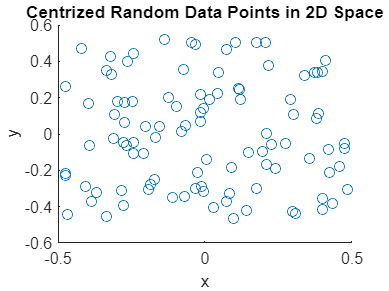

% Plot the data points
scatter(r_x, r_y);
xlabel("x");
ylabel("y");
title("Centrized Random Data Points in 2D Space");

cov_mat_Q1 = cov(r_x, r_y)

cov_mat_Q1 =     0.0756   -0.0013
   -0.0013    0.0846


[e_vec1, e_val1] = eig(cov(r_x, r_y))

e_vec1 =    -0.9907   -0.1358
   -0.1358    0.9907


e_val1 =     0.0754         0
         0    0.0848


% Q2
folders = dir('Face\training');
folders = folders(~ismember({folders.name}, {'.', '..'}));
subFolders = folders([folders.isdir]);
mat = []


mat =

     []



mean_mat = []


mean_mat =

     []



for K = 1:length(subFolders)
    cur_dr = ['Face\training\' subFolders(K).name];
    images = dir(cur_dr);
    images = images(~ismember({images.name},{'.','..'}));
    for i = 1:length(images)
        img = imread([cur_dr '\' images(i).name]);
        img = img(:, :, 1);        %turning the image into a greyside by only cosididering the first channel
        img = reshape(img, [], 1);
        mat = [mat img];
    end
end
mean_mat = mean(mat, 2);
% size(mat)
% whos("mat")

% Making our data X
im2 = reshape(mean_mat, [112, 92])

im2 =    95.7000   95.5594   95.9188   95.7844   96.0094   96.2750   96.1469   95.7469   96.0375   95.9625   95.6875   95.3594   94.6031   94.4656   94.1344   93.6281   93.4594   92.6000   92.3438   92.2188   92.7125   92.9219   91.9813   90.8125   89.5094   88.4781   86.9375   86.2687   84.9437   84.0719   84.1188   83.3500   82.6406   82.0094   82.5187   81.9688   82.6656   83.7000   82.5344   83.1281   82.7750   82.9656   82.9031   81.9313   81.8594   81.1937   80.7938   80.3906   81.9250   81.9250
   95.8063   96.0125   95.7031   95.7625   96.1906   95.9844   95.8250   95.9313   95.6125   95.5438   95.1781   94.7406   93.8156   93.5406   93.2938   92.6156   92.3406   92.3625   91.7281   91.0750   91.0844   91.5062   89.9000   89.2812   87.5469   86.2719   85.2438   84.7281   83.3781   83.5000   83.2094   83.2000   82.2219   83.1063   83.4688   83.4719   83.8219   85.4281   84.7156   84.0187   84.1562   84.4313   83.9406   83.2750   83.1719   82.9156   82.3125   82.1125   81.7500   

im3 = cast(im2, "uint8")

im3 = 112×92 uint8 matrix
    96    96    96    96    96    96    96    96    96    96    96    95    95    94    94    94    93    93    92    92    93    93    92    91    90    88    87    86    85    84    84    83    83    82    83    82    83    84    83    83    83    83    83    82    82    81    81    80    82    82
    96    96    96    96    96    96    96    96    96    96    95    95    94    94    93    93    92    92    92    91    91    92    90    89    88    86    85    85    83    84    83    83    82    83    83    83    84    85    85    84    84    84    84    83    83    83    82    82    82    81
    96    96    96    96    96    96    96    96    95    95    94    94    93    92    92    92    92    91    90    90    90    89    88    87    85    85    85    84    84    84    85    85    85    85    85    84    85    86    86    86    86    86    86    85    85    85    85    84    83    83
    96    96    96    96    95    96    96    95    95    94    93    9

lol = size(im3)

lol =    112    92


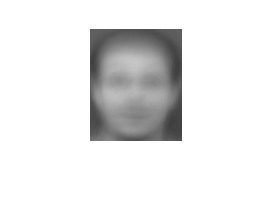

imshow(im3)

imwrite(im3, "mean.bmp")
%Subtract the mean image from all the samples
data_X = []


data_X =

     []



for K = 1:320
    %temp = reshape(mat(:, K), [112, 92]);
    subs = cast(mat(:, K), "double") - mean_mat;
    d_subs = size(subs);
    
    data_X = [data_X subs];
end

%2.5
size(data_X)

ans =        10304         320


trans_data_X = data_X'

trans_data_X =   -53.7000  -56.8063  -56.9813  -52.8031  -56.0344  -55.7719  -56.7562  -55.7500  -53.8844  -48.0687  -48.6594  -50.9656  -46.7969  -46.5312  -42.7500  -52.3969  -48.8375  -46.8625  -45.2562  -40.5000  -39.2656  -28.0281  -29.0656  -18.6750  -25.3812  -24.3312  -20.0812  -30.7375  -28.3688  -30.6781  -40.3937  -35.2344  -20.0094  -12.8750   -4.1750   -2.9156  -12.8875  -18.4250  -30.5563  -31.2906  -28.9813  -26.7125  -33.5594  -34.1437  -31.5750  -35.5187  -36.5094  -37.1781  -38.0375   29.3312
  -28.7000  -31.8063  -19.9813   -6.8031  -42.0344  -48.7719  -39.7562  -39.7500  -33.8844  -15.0687  -19.6594   -8.9656  -13.7969  -17.5312  -17.7500   -8.3969  -12.8375    0.1375  -13.2562    0.5000   -2.2656   10.9719  -14.0656    9.3250   23.6188   24.6688   15.9188   19.2625   19.6312   25.3219   26.6063   18.7656   26.9906   16.1250   16.8250   25.0844   28.1125   26.5750   40.4437   17.7094   18.0187   19.2875   27.4406   26.8563   32.4250   50.4813   71.4906   85.8219   8

T = (trans_data_X*data_X)/320

T = 1.0e+05 *

    0.5031    0.1547    0.2974    0.2162    0.1959    0.2086    0.3750    0.3756   -0.0155    0.0548    0.0536    0.0347    0.1403    0.0711    0.0864    0.1170    0.0056   -0.0032    0.0538    0.1201    0.1016   -0.0087   -0.0008   -0.0110    0.2229    0.0604    0.0287    0.0267    0.0563    0.1437    0.0421    0.1268   -0.0244   -0.0317    0.0434    0.0309    0.0252   -0.0055    0.0306    0.0447   -0.0826   -0.0766   -0.0886   -0.0816   -0.1320   -0.0132   -0.0293   -0.0083    0.0336   -0.1559
    0.1547    1.1627    0.3802    0.5555    0.8248    0.4856    0.5670    0.3822   -0.3000   -0.2973   -0.2315   -0.1452   -0.0930   -0.1324   -0.2268   -0.2212   -0.3191   -0.3000   -0.2254   -0.0897   -0.1422   -0.3295   -0.3033   -0.2030    0.3554    0.1635    0.1802    0.1199    0.1517    0.2639    0.1110    0.3808    0.2084    0.2740    0.6031    0.5037    0.1905    0.2848    0.2697    0.3032    0.0209    0.0413   -0.0097   -0.0534   -0.0010   -0.1797   -0.1889   -0.1224    

size(T)

ans =    320   320




%Question 6 and Question 5


% First we calculate the eigenvalues and vectors for T with the dimensions
% 320*320
[evec_Q2, eval_Q2] = eig(T)

evec_Q2 =     0.0243    0.0016   -0.1103    0.0139   -0.0310    0.0014    0.0304   -0.0028   -0.0265   -0.1214   -0.0032    0.0486    0.0495   -0.0253    0.0143    0.0683    0.0075    0.0740    0.0182   -0.0307    0.0264    0.0164   -0.0804   -0.0335   -0.0201    0.0216    0.0440   -0.0699    0.0001    0.0274    0.0634    0.0061    0.0354    0.0424   -0.0019   -0.0551    0.0437   -0.0627    0.0651   -0.0022    0.0433   -0.1038    0.0102    0.0272    0.0085    0.0208   -0.0327   -0.0005   -0.0189    0.0826
    0.0944   -0.0140    0.0101   -0.0008   -0.1857    0.0319   -0.0072   -0.1199   -0.0551   -0.0073   -0.0204    0.0128   -0.0038    0.1378    0.0301   -0.0192   -0.0175    0.0220   -0.1166   -0.1058   -0.0593    0.0607   -0.0023   -0.0784   -0.0674    0.0297    0.0153    0.0552    0.0934   -0.0212   -0.0670    0.1030   -0.0209    0.0227    0.0428   -0.1216    0.0351    0.0027   -0.0690    0.0085    0.0906   -0.0438    0.0034    0.0229    0.0085   -0.0288   -0.0838   -0.0969   -0.077

eval_Q2 = 1.0e+06 *

    4.4491         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    3.4471         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

v_i = data_X*evec_Q2

v_i =   261.8858  548.4714  389.9992   78.2067  115.5836 -100.4360  109.9978  -94.9946  -20.7877  -20.2755  -67.2054  -79.8613   74.2539  -79.2281    3.0817  -20.8620    6.0477  -30.3074  -11.3936   67.2032  -81.4959  -69.7966   12.7662   23.3075   62.8045  -44.8124  -26.5118   44.8910  -23.3247  -14.0463  -38.9409   16.2472   20.4729  -31.5973   19.9208   10.5019   10.8510  -76.5824   -5.6746   -4.5842   41.7878  -12.7683    0.6103    3.5557  -33.9170  -27.2899   11.5783   47.7725   30.0000  -14.5794
  260.1584  547.9329  395.0578   76.5713  118.9124  -97.6770  105.3381  -94.2633  -22.0134  -22.3739  -62.1603  -78.9918   66.3199  -82.4463   10.7544  -22.8873    0.7265  -21.9992   -7.2581   65.7620  -73.5228  -71.0234    9.9888   23.9961   63.8776  -44.0617  -28.5778   47.2030  -18.3052  -13.1042  -40.8028   18.5401   21.9251  -35.4820   20.1059   12.0952   10.9682  -68.4603   -2.7085   -9.5717   41.5587  -10.0205   -3.0199    2.6248  -29.9228  -26.4570   14.2753   42.7724   27.7796  -

max_6_eig_vec_total = [];
min_6_eig_vec_total = [];
[max_eig_val_Q2, num] = maxk(diag(eval_Q2), 6)

max_eig_val_Q2 = 1.0e+06 *

    4.4491
    3.4471
    1.5136
    1.2750
    1.0001
    0.8051


num =      1
     2
     3
     4
     5
     6


[min_eig_val_Q2, num_min] = mink(diag(eval_Q2), 6)

min_eig_val_Q2 = 1.0e+03 *

   -0.0000
    2.3794
    2.4139
    2.6046
    2.8478
    2.8873


num_min =     67
   146
   147
   148
   159
   149


temp_var =   261.8858  260.5968  259.7689  252.8471  260.1315  267.5886  275.2836  265.6482  271.0754  280.9206  280.5485  288.2429  306.7642  316.1893  323.4667  317.7312  318.8104  337.8377  352.6336  365.1564  377.4507  398.3185  422.8539  434.8806  449.8302  483.0290  515.3632  521.2026  524.5073  536.0502  530.8626  529.5559  518.5283  543.7916  534.3348  527.2872  545.4945  523.0812  518.9737  535.5981  536.5748  527.7070  518.6439  519.1713  522.9847  519.4151  518.6152  511.4559  515.1744  511.6750
  260.1584  260.9505  248.8105  263.4058  263.3778  273.7563  273.8025  260.8948  274.0896  279.7088  294.0895  303.3260  310.2684  307.5408  332.3554  337.8247  348.0335  351.1295  374.5760  381.2741  396.4877  433.5590  450.0756  462.7127  486.8952  521.6277  535.8235  547.1560  540.0145  550.1670  549.9958  547.6149  536.6341  546.4864  543.9352  539.6175  550.2957  553.8665  536.3590  530.8914  529.2967  522.1900  507.3649  514.7528  529.5149  518.2164  524.4512  521.9183  514.84

name_of_file_1 = "Q5_1thEigen.bmp"

temp_var_1 = 1.0e-11 *

    0.1316    0.1690    0.1980    0.1528    0.1447    0.1956    0.1423    0.1555    0.2359    0.1550    0.1234    0.0454    0.2000    0.1735    0.0282    0.0631   -0.0569   -0.0553    0.0821    0.2026    0.3331    0.1326   -0.0305   -0.0316   -0.1383   -0.0973    0.2176    0.1293    0.0671    0.0500    0.1179   -0.0165    0.3928    0.2616   -0.0690    0.0188   -0.0756    0.1791    0.0669   -0.0043    0.1785   -0.0641   -0.1110   -0.1221   -0.1001   -0.0685    0.0274    0.0729    0.0811   -0.1135
    0.1061    0.1689    0.1531    0.1577    0.1853    0.1457    0.1890    0.0888    0.2169    0.1632    0.0908    0.1432    0.0698    0.0001    0.0585   -0.0345   -0.0812    0.1076    0.1079    0.1863    0.1700   -0.0029   -0.1663   -0.0318   -0.1257    0.0802    0.2111    0.2321    0.2195    0.1583    0.0143    0.1123    0.2793    0.1645    0.0965    0.1872    0.1237    0.1845    0.1492    0.0389    0.0941    0.1061    0.1009   -0.0624    0.1281    0.1075    0.2233    0

name_of_file_2 = "Q6_1thEigen.bmp"

temp_var =   548.4714  546.8309  551.0017  552.7036  552.5321  548.5336  542.6903  548.1690  543.7229  541.3720  537.9449  530.7772  532.3376  502.5530  496.1055  505.0443  481.6777  449.6501  440.9303  425.0601  403.2213  362.4016  344.1388  330.4466  301.1725  258.9970  225.8449  217.0207  200.2067  167.4521  150.1646  121.4202  114.4393  105.3421   83.9718   89.6022   74.8903   66.6700   63.2107   46.0192   56.8152   69.4681   73.7003   57.7056   60.9618   63.6616   66.4409   84.0168   93.1331  118.3172
  547.9329  548.5714  544.4194  549.8335  546.4306  542.9862  543.7785  540.9601  532.7144  539.7788  532.7350  512.8503  504.7288  501.8401  489.7037  481.3334  448.2685  424.9587  411.0268  390.3710  350.7566  316.5602  295.2490  253.8382  241.1335  193.0491  160.3763  129.3529  118.9523  111.0311   78.6441   56.8625   47.1352   40.3290   11.7351    4.7970   -1.3414  -20.4218  -10.7093  -31.8233  -38.0981  -14.5770  -27.7705  -25.8698  -27.5121  -26.6142  -18.5176    4.3489   22.93

name_of_file_1 = "Q5_2thEigen.bmp"

temp_var_1 =     3.0214    3.2307    1.4562    8.2091    3.9676    7.4775   -1.0650   -0.9700    5.1857    4.7563    3.7376   -4.3206   -3.9657   -5.3066    0.1707   -3.2548  -10.8097  -10.3594    4.9831    1.0667    4.3886   -1.4978   -3.6585   -4.7518   -9.8935  -17.9280   -4.4332  -10.3761  -10.7075  -13.5837   -6.3681   -1.2521    2.8309    6.4946   -0.3164    7.0833    1.1541    8.5842   10.3418    5.1873   -4.5495    5.3586    2.9479    8.6391    5.9663   19.1876   12.5228    9.2376    2.5249    2.7303
    6.8184    7.8756    1.3719    5.9308    6.9779    2.7423    1.9226   -2.4807    2.6069    4.2035    2.2587   -0.5120   -2.8101    5.1888   -4.9140   -5.6214  -10.6191   -8.2975   -7.7431    3.3364    0.1132    0.8873   -7.1617  -10.9572  -15.8102    3.1441   -9.0851    3.1204   -4.8281   -4.3710   -1.6279   -2.8910   -0.0070    0.3136   -8.1896   -2.8340   -4.5113   -1.2142   -3.1061    1.7089   -4.4199    8.8746    0.7839   -1.5768    6.7716    4.2849   11.5513   16.5533    4.

name_of_file_2 = "Q6_2thEigen.bmp"

temp_var =   389.9992  392.3659  389.2323  390.4757  391.4500  389.2840  401.8343  405.0120  393.9119  392.1716  392.7132  386.5584  379.4290  372.5928  367.1668  362.5404  383.6496  399.6866  405.3135  403.6162  397.2635  395.4573  405.7365  410.8001  401.7546  418.7530  411.7847  406.3739  377.9602  369.9243  358.1203  326.4349  317.0567  334.6862  341.6371  345.0561  332.0028  317.7769  326.1611  324.5634  323.8588  312.7574  321.4897  310.7233  317.6605  323.3255  300.3829  318.0370  334.8383  336.9234
  395.0578  388.9792  392.8374  391.9834  392.2398  390.4143  400.9084  405.3349  402.3814  388.9961  379.9758  389.4604  379.1652  378.3858  366.0728  368.8405  389.3460  396.9636  392.4807  381.3974  383.8845  391.6020  404.5585  400.9431  397.1624  383.0041  378.9155  369.1309  346.3244  349.9971  344.2646  323.8827  312.3597  334.0540  339.7950  344.3661  318.4119  318.3652  319.5207  308.6937  293.0489  284.8658  298.1401  291.0448  288.3660  290.6873  291.7838  308.9691  301.90

name_of_file_1 = "Q5_3thEigen.bmp"

temp_var_1 =     1.3357    0.7071    5.2575    2.0351    3.9158    5.7588    4.7130    8.1165    4.9148    8.2096    9.1934    5.1290    9.0061    6.5803   -9.5742  -27.9716  -12.3478  -16.1155    1.4912    7.2555   13.2903   13.5028    2.1668    0.1528   -6.5353  -10.8613   16.4291   10.1950  -10.2418   -8.4892   -4.5549  -12.5595  -11.3531   -9.2697   -9.7126   -7.4975    5.9336   10.9773    6.2207    8.0951   -0.4840  -10.3302  -11.0156  -17.6884   -4.7019  -18.4693  -13.8221  -12.8435  -14.3167   -5.8415
    3.5364    4.7036    6.7813    0.5073    0.7104    6.7632    3.3382    4.3142    7.3973    5.5275    1.4322    2.3196    4.7053   10.6136    2.1719   -7.3992   -6.0775   -5.9834   -1.3572    2.5626    4.8212   14.8042    3.6619    2.8973   -3.7766  -21.1809   -4.7542    9.8602    3.7589   -3.9702    7.3091    4.0763    1.7367   -9.4028   -3.1279   -6.9152   -5.7488   22.9216   20.3337   14.6257    7.1538   13.8084    4.3689   -0.0167    5.1779    3.4797   -7.0157   -4.6322  -12.

name_of_file_2 = "Q6_3thEigen.bmp"

temp_var =    78.2067   79.1703   82.9080   81.2917   86.0207   82.3118   71.9827   77.0959   68.9834   72.4441   64.6219   67.9482   65.4413   66.7326   73.7628   45.1284   49.5835   59.1913   44.2733   44.2296   25.2317    0.8226   -2.0524  -26.3105  -16.6506  -28.3049  -43.7620  -57.7070  -84.5335  -97.6554 -115.6307 -123.7082 -128.5802 -128.7788 -138.3287 -132.8505 -150.2489 -162.8555 -165.5526 -172.3101 -171.8822 -178.8405 -179.7143 -177.1595 -185.4723 -176.3992 -172.5602 -162.2779 -160.9464 -176.4986
   76.5713   82.2210   85.1757   78.3633   84.5225   78.5777   71.7308   70.8692   65.2034   65.7016   57.6008   69.9668   67.1533   67.4828   53.1031   45.9970   45.7496   47.5871   44.6299   26.1583    5.2616   -4.5960   -5.4990  -36.7919  -45.4392  -60.5969  -63.7583  -79.2052 -100.4851 -118.7309 -131.0587 -153.3524 -167.4911 -167.2033 -175.0270 -183.1449 -187.5587 -192.5788 -202.5976 -207.5259 -226.6145 -237.0101 -221.8918 -223.0834 -210.0708 -208.0870 -211.4796 -202.3332 -199.55

name_of_file_1 = "Q5_4thEigen.bmp"

temp_var_1 =    -1.0064   -0.6855    6.3932    2.2424   -1.1071    4.9838    2.8171   -0.0549    0.8860   -1.4034    1.3002   -5.6518   -0.7576    0.1163    7.1598   15.3498    7.3989    2.9228   -1.1669    9.8529    3.8094   15.1214   -3.0275   -7.0288   -1.1759   -7.0045   -6.4407   -1.7277   -9.2752  -13.5550  -12.3127  -18.7043   -0.1696    9.7213   -7.6750  -16.4364   -0.4998   -0.7090    7.9047   -1.1608    7.1012   -2.9996   -6.4561   -5.0978   14.2681    2.7709   -6.0275    5.0272   -4.7157  -10.9380
   -0.3191    5.9584    2.0694    0.6868   -0.6243   10.7435    0.8721   -2.5036   -1.2468    4.6673    6.1104    4.6010    8.3593   -0.9357   -0.6312    7.0038    9.4959    2.9700    9.3158   -2.4240   -4.8099   -1.1572   -5.6229   -8.6177    3.0106    4.7302   -4.4124    5.3559  -14.0904   -8.8845   -3.1815  -19.3653    0.8987   -2.4324   -2.3610   -4.5346   -0.6109   -3.9142    3.2840   -7.3144   -0.6929   -6.0750   -9.7142   -6.6495   -0.0200    3.1827    4.3150   -6.6623    1.

name_of_file_2 = "Q6_4thEigen.bmp"

temp_var =   115.5836  117.6160  123.2875  120.6800  122.9198  112.3150  120.2382  121.5895  119.6214  118.8314   98.1150   87.8479   72.3676   78.1782   88.3286   75.9877   76.5655   90.8726   75.4220   56.4521   55.2108   60.0666   31.4487   17.3582   -7.8723    8.2802  -11.2866  -33.4991  -40.8106  -44.8075  -50.4604  -52.7860  -47.8132  -33.8038  -42.3014  -44.3991  -37.0411  -25.4544  -31.4119  -34.4418  -42.0971  -49.8541  -45.8945  -43.9089  -43.3508  -36.7243  -49.9627  -42.5888  -51.0587  -73.5880
  118.9124  115.9151  128.7613  119.2125  111.7226  115.7609  120.7368  124.8964  107.2248  103.1793   84.1345   72.7928   70.8717   82.0552   78.2795   72.6950   58.4372   70.3893   60.2828   41.0119   34.9613   26.8187    3.8128    5.0620  -19.1103  -14.9447  -18.8814  -40.6919  -42.2040  -42.5237  -42.7696  -49.0583  -48.0327  -36.5305  -35.7297  -37.5877  -25.6065  -15.3524  -18.8704  -25.7515  -29.0497  -32.9811  -35.6796  -29.7464  -33.4969  -25.4264  -37.2133  -49.3112  -69.99

name_of_file_1 = "Q5_5thEigen.bmp"

temp_var_1 =     8.1908   -2.7376    7.8044   -1.0116   -0.4979    0.1548   -0.9891    1.1383   -4.6368   -0.6752    2.9092   -2.0993   -2.9029   -0.8693   -3.8956   -3.8030  -10.9319   -8.1083   10.7078   12.6564    4.0061   18.2505   -9.1993   -4.1184    0.9563  -10.9085   -7.2983    9.3518   -8.5626   -6.6785   10.0364    1.0725    1.6008   -5.0021   14.3359    3.3534   19.0953  -11.4651    0.7122   -0.6501   -5.5056    5.7281    2.4822   -5.4635   -5.3840   -0.7484   -3.4603  -10.6320   -3.1934  -13.4316
    3.9309   -0.6811   -2.8708    7.2610   -6.8363    1.6562    1.4976    6.1632   -3.4773   -1.6292   -8.1277   -9.4399   -5.3178   -8.9043   -8.2644   -0.0228   -9.1054    7.3539    4.5934    3.4845    0.2544   -2.3032    9.1039    9.6012   -7.3893  -19.2000  -14.3693    4.9213  -14.5486  -12.1435   -1.9580  -20.2961   -1.6198   -2.2756    0.0239   -0.6130   -0.2095   -1.5316  -10.1677   11.9744   11.8168   -5.9257   14.6446   -6.4769  -20.6477   -2.5590   -8.7625   -0.6387  -11.

name_of_file_2 = "Q6_5thEigen.bmp"

temp_var =  -100.4360  -90.1324  -86.8334  -90.8840  -87.8064  -91.7729  -87.9260  -83.3261  -94.3063  -89.6533  -79.8798  -77.2499  -72.6758  -85.9539  -93.1293  -92.3118  -90.7006  -84.7007  -85.7134  -88.0711  -96.8592 -105.0582  -65.3243  -68.2967  -48.2819  -37.5015  -36.2997  -49.6024  -32.3994  -26.7028  -24.5670  -36.7758  -49.7926  -43.7386  -62.9489  -72.5775  -59.0743  -74.9232  -81.7359 -103.7307 -107.5979 -134.0149 -147.2864 -148.2116 -169.4196 -162.7398 -164.6646 -180.0934 -185.3120 -188.0379
  -97.6770  -87.9604  -91.0122  -96.6525  -90.7948  -89.3814  -93.6729  -87.5898  -87.3935  -83.3019  -77.6567  -77.5354  -81.4249  -72.4442  -79.9568  -92.6606 -103.2732  -84.2153  -71.1153  -88.1199  -98.5652 -100.3588  -75.1459  -74.9249  -58.8828  -47.8703  -42.5767  -36.0262  -47.0842  -32.4983  -37.6245  -47.0447  -62.2992  -58.6011  -69.7480  -89.1614  -83.6723  -98.0630 -122.1064 -144.6660 -148.6000 -175.2669 -189.6545 -198.2833 -211.4769 -197.2624 -194.0470 -202.8373 -224.18

name_of_file_1 = "Q5_6thEigen.bmp"

temp_var_1 =     0.8986   -0.0881   -5.1186    2.6188    1.9135   -1.7330   -0.2588    4.5276    3.1670   -0.8997   -5.5400   -0.9969    0.9926   -3.7354    3.8918    4.9811    9.1498   -4.7814   -1.4181   -0.2395   -1.9161    5.8356   -2.5789   12.9543    9.3648   -6.7414   -3.4603   -0.4243   21.6477   23.3350    9.5910   13.0266    5.6929   -7.8912   17.7256    7.6679    0.0924   -5.9284   -2.9714   -3.5619   -2.7141   13.3754   11.7357   -1.9683    6.6291   -3.4483    6.5202   -0.0035   -9.2900  -14.9552
   -2.1088   -0.3416   -0.4834    0.6628   -3.2941    2.9747   -2.8601   -2.9602   -0.3876    0.5202    5.7820    9.5639    5.4193    3.8807    5.6621    0.5149    0.7613   -6.7176   -3.0722   -6.6532   -1.2212    4.5611   -9.5740    4.3957   -0.4643    6.5531   -6.8252    1.6053    9.8698   -0.2998   -0.7098  -10.1653    7.8814  -14.9802   -6.2088    5.7751   10.6335   -1.7730   -5.7789   -6.5976    0.1417   -0.7568    1.4400    1.9886    5.0107    4.8625   -0.3543    3.0509    3.

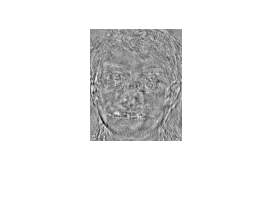

name_of_file_2 = "Q6_6thEigen.bmp"

for i = 1:length(num)
    max_six_eigenvec = v_i(:, i);
    min_six_eigenvec = v_i(:, num_min(i));
    max_6_eig_vec_total = [max_6_eig_vec_total max_six_eigenvec];
    min_6_eig_vec_total = [min_6_eig_vec_total min_six_eigenvec];
end
temp_var = [];
for i = 1:6
    temp_var = reshape(max_6_eig_vec_total(:, i), [112, 92])
    %temp_var = cast(temp_var, "uint8")
    temp_var = (temp_var - min(temp_var, [], 'all')) / (max(temp_var, [], 'all') - min(temp_var, [], 'all'));
    imshow(temp_var)
    name_of_file_1 = sprintf("Q5_%dthEigen.bmp", i)
    imwrite(temp_var, name_of_file_1)
    temp_var_1 = reshape(min_6_eig_vec_total(:, i), [112, 92])
    temp_var_1 = (temp_var_1 - min(temp_var_1, [], 'all')) / (max(temp_var_1, [], 'all') - min(temp_var_1, [], 'all'));
    %temp_var_1 = cast(temp_var_1, "uint8")
    imshow(temp_var_1)
    name_of_file_2 = sprintf("Q6_%dthEigen.bmp", i)
    imwrite(temp_var_1, name_of_file_2)
end


%reshaped_version = reshape(largest_6_vec, [112, 92])

%Question 7
[U, D, V] = svd(data_X)

U =     0.0069    0.0165    0.0177    0.0039    0.0065   -0.0063   -0.0080    0.0072   -0.0017    0.0018    0.0063    0.0078    0.0081   -0.0089    0.0004    0.0025    0.0007    0.0038   -0.0015    0.0091   -0.0112    0.0102   -0.0019    0.0036   -0.0100   -0.0073   -0.0044    0.0039   -0.0076    0.0025   -0.0069   -0.0029    0.0038    0.0059   -0.0037    0.0020    0.0021   -0.0152   -0.0011   -0.0010    0.0089   -0.0027    0.0001   -0.0008   -0.0075    0.0061   -0.0026   -0.0109   -0.0071    0.0035
    0.0069    0.0165    0.0180    0.0038    0.0066   -0.0061   -0.0077    0.0071   -0.0018    0.0020    0.0059    0.0077    0.0072   -0.0093    0.0013    0.0028    0.0001    0.0028   -0.0009    0.0089   -0.0101    0.0104   -0.0015    0.0038   -0.0102   -0.0072   -0.0048    0.0031   -0.0080    0.0023   -0.0073   -0.0033    0.0040    0.0066   -0.0038    0.0023    0.0022   -0.0136   -0.0005   -0.0020    0.0088   -0.0021   -0.0007   -0.0006   -0.0066    0.0059   -0.0033   -0.0098   -0.0066    0

D = 1.0e+04 *

    3.7732         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    3.3213         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

V =     0.0243    0.0016   -0.1103    0.0139   -0.0310    0.0014   -0.0304    0.0028   -0.0265    0.1214    0.0032   -0.0486    0.0495   -0.0253    0.0143   -0.0683    0.0075   -0.0740    0.0182   -0.0307    0.0264   -0.0164    0.0804   -0.0335    0.0201    0.0216    0.0440   -0.0001    0.0699   -0.0274    0.0634   -0.0061    0.0354   -0.0424    0.0019   -0.0551    0.0437   -0.0627    0.0651   -0.0022    0.0433   -0.1038    0.0102   -0.0272    0.0085   -0.0208    0.0327    0.0005    0.0189   -0.0826
    0.0944   -0.0140    0.0101   -0.0008   -0.1857    0.0319    0.0072    0.1199   -0.0551    0.0073    0.0204   -0.0128   -0.0038    0.1378    0.0301    0.0192   -0.0175   -0.0220   -0.1166   -0.1058   -0.0593   -0.0607    0.0023   -0.0784    0.0674    0.0297    0.0153   -0.0934   -0.0552    0.0212   -0.0670   -0.1030   -0.0209   -0.0227   -0.0428   -0.1216    0.0351    0.0027   -0.0690    0.0085    0.0906   -0.0438    0.0034   -0.0229    0.0085    0.0288    0.0838    0.0969    0.0777   -0

eig_faces_SVD = U

eig_faces_SVD =     0.0069    0.0165    0.0177    0.0039    0.0065   -0.0063   -0.0080    0.0072   -0.0017    0.0018    0.0063    0.0078    0.0081   -0.0089    0.0004    0.0025    0.0007    0.0038   -0.0015    0.0091   -0.0112    0.0102   -0.0019    0.0036   -0.0100   -0.0073   -0.0044    0.0039   -0.0076    0.0025   -0.0069   -0.0029    0.0038    0.0059   -0.0037    0.0020    0.0021   -0.0152   -0.0011   -0.0010    0.0089   -0.0027    0.0001   -0.0008   -0.0075    0.0061   -0.0026   -0.0109   -0.0071    0.0035
    0.0069    0.0165    0.0180    0.0038    0.0066   -0.0061   -0.0077    0.0071   -0.0018    0.0020    0.0059    0.0077    0.0072   -0.0093    0.0013    0.0028    0.0001    0.0028   -0.0009    0.0089   -0.0101    0.0104   -0.0015    0.0038   -0.0102   -0.0072   -0.0048    0.0031   -0.0080    0.0023   -0.0073   -0.0033    0.0040    0.0066   -0.0038    0.0023    0.0022   -0.0136   -0.0005   -0.0020    0.0088   -0.0021   -0.0007   -0.0006   -0.0066    0.0059   -0.0033   -0.0098   

eig_val_SVD = (diag(D).^2)/320

eig_val_SVD = 1.0e+06 *

    4.4491
    3.4471
    1.5136
    1.2750
    1.0001
    0.8051
    0.5892
    0.5445
    0.4772
    0.4113


eig_6_max_vec_SVD = []


eig_6_max_vec_SVD =

     []



[eig_val_SVD_sorted, eig_val_indices] = sort(eig_val_SVD, 'descend');
for i = 1:6
    eig_6_max_vec_SVD = eig_faces_SVD(:, eig_val_indices(i))
    eig_6_max_vec_SVD = reshape(eig_6_max_vec_SVD, [112, 92])
    name_of_file_3 = sprintf("Q7_%dthEigen.bmp", i)
    %imshow(eig_6_max_vec_SVD, [])
    eig_6_max_vec_SVD = (eig_6_max_vec_SVD - min(eig_6_max_vec_SVD, [], 'all')) / (max(eig_6_max_vec_SVD, [], 'all') - min(eig_6_max_vec_SVD, [], 'all'));
    imwrite(eig_6_max_vec_SVD, name_of_file_3)
end

eig_6_max_vec_SVD =     0.0069
    0.0069
    0.0069
    0.0069
    0.0066
    0.0065
    0.0066
    0.0066
    0.0067
    0.0067


eig_6_max_vec_SVD =     0.0069    0.0069    0.0069    0.0067    0.0069    0.0071    0.0073    0.0070    0.0072    0.0074    0.0074    0.0076    0.0081    0.0084    0.0086    0.0084    0.0084    0.0090    0.0093    0.0097    0.0100    0.0106    0.0112    0.0115    0.0119    0.0128    0.0137    0.0138    0.0139    0.0142    0.0141    0.0140    0.0137    0.0144    0.0142    0.0140    0.0145    0.0139    0.0138    0.0142    0.0142    0.0140    0.0137    0.0138    0.0139    0.0138    0.0137    0.0136    0.0137    0.0136
    0.0069    0.0069    0.0066    0.0070    0.0070    0.0073    0.0073    0.0069    0.0073    0.0074    0.0078    0.0080    0.0082    0.0082    0.0088    0.0090    0.0092    0.0093    0.0099    0.0101    0.0105    0.0115    0.0119    0.0123    0.0129    0.0138    0.0142    0.0145    0.0143    0.0146    0.0146    0.0145    0.0142    0.0145    0.0144    0.0143    0.0146    0.0147    0.0142    0.0141    0.0140    0.0138    0.0134    0.0136    0.0140    0.0137    0.0139    0.013

name_of_file_3 = "Q7_1thEigen.bmp"

eig_6_max_vec_SVD =     0.0165
    0.0165
    0.0164
    0.0164
    0.0164
    0.0162
    0.0161
    0.0162
    0.0160
    0.0158


eig_6_max_vec_SVD =     0.0165    0.0165    0.0166    0.0166    0.0166    0.0165    0.0163    0.0165    0.0164    0.0163    0.0162    0.0160    0.0160    0.0151    0.0149    0.0152    0.0145    0.0135    0.0133    0.0128    0.0121    0.0109    0.0104    0.0099    0.0091    0.0078    0.0068    0.0065    0.0060    0.0050    0.0045    0.0037    0.0034    0.0032    0.0025    0.0027    0.0023    0.0020    0.0019    0.0014    0.0017    0.0021    0.0022    0.0017    0.0018    0.0019    0.0020    0.0025    0.0028    0.0036
    0.0165    0.0165    0.0164    0.0166    0.0165    0.0163    0.0164    0.0163    0.0160    0.0163    0.0160    0.0154    0.0152    0.0151    0.0147    0.0145    0.0135    0.0128    0.0124    0.0118    0.0106    0.0095    0.0089    0.0076    0.0073    0.0058    0.0048    0.0039    0.0036    0.0033    0.0024    0.0017    0.0014    0.0012    0.0004    0.0001   -0.0000   -0.0006   -0.0003   -0.0010   -0.0011   -0.0004   -0.0008   -0.0008   -0.0008   -0.0008   -0.0006    0.000

name_of_file_3 = "Q7_2thEigen.bmp"

eig_6_max_vec_SVD =     0.0177
    0.0180
    0.0177
    0.0178
    0.0177
    0.0177
    0.0175
    0.0177
    0.0175
    0.0173


eig_6_max_vec_SVD = 112×92
    0.0177    0.0178    0.0177    0.0177    0.0178    0.0177    0.0183    0.0184    0.0179    0.0178    0.0178    0.0176    0.0172    0.0169    0.0167    0.0165    0.0174    0.0182    0.0184    0.0183    0.0181    0.0180    0.0184    0.0187    0.0183    0.0190    0.0187    0.0185    0.0172    0.0168
    0.0180    0.0177    0.0179    0.0178    0.0178    0.0177    0.0182    0.0184    0.0183    0.0177    0.0173    0.0177    0.0172    0.0172    0.0166    0.0168    0.0177    0.0180    0.0178    0.0173    0.0174    0.0178    0.0184    0.0182    0.0180    0.0174    0.0172    0.0168    0.0157    0.0159
    0.0177    0.0178    0.0176    0.0179    0.0177    0.0180    0.0183    0.0183    0.0182    0.0177    0.0174    0.0180    0.0178    0.0169    0.0168    0.0171    0.0178    0.0179    0.0172    0.0169    0.0175    0.0177    0.0172    0.0170    0.0161    0.0162    0.0160    0.0158    0.0159    0.0151
    0.0178    0.0180    0.0176    0.0181    0.0179    0.0180    0.0183

name_of_file_3 = "Q7_3thEigen.bmp"

eig_6_max_vec_SVD = 10304×1
    0.0039
    0.0038
    0.0040
    0.0040
    0.0038
    0.0043
    0.0044
    0.0044
    0.0043
    0.0042


eig_6_max_vec_SVD = 112×92
    0.0039    0.0039    0.0041    0.0040    0.0043    0.0041    0.0036    0.0038    0.0034    0.0036    0.0032    0.0034    0.0032    0.0033    0.0037    0.0022    0.0025    0.0029    0.0022    0.0022    0.0012    0.0000   -0.0001   -0.0013   -0.0008   -0.0014   -0.0022   -0.0029   -0.0042   -0.0048
    0.0038    0.0041    0.0042    0.0039    0.0042    0.0039    0.0036    0.0035    0.0032    0.0033    0.0029    0.0035    0.0033    0.0033    0.0026    0.0023    0.0023    0.0024    0.0022    0.0013    0.0003   -0.0002   -0.0003   -0.0018   -0.0022   -0.0030   -0.0032   -0.0039   -0.0050   -0.0059
    0.0040    0.0040    0.0041    0.0038    0.0042    0.0040    0.0038    0.0030    0.0029    0.0028    0.0025    0.0029    0.0027    0.0028    0.0020    0.0017    0.0021    0.0017    0.0016    0.0011    0.0007    0.0001   -0.0012   -0.0024   -0.0030   -0.0041   -0.0048   -0.0051   -0.0058   -0.0074
    0.0040    0.0039    0.0042    0.0039    0.0040    0.0038    0.0038

name_of_file_3 = "Q7_4thEigen.bmp"

eig_6_max_vec_SVD = 10304×1
    0.0065
    0.0066
    0.0065
    0.0067
    0.0068
    0.0071
    0.0073
    0.0069
    0.0067
    0.0066


eig_6_max_vec_SVD = 112×92
    0.0065    0.0066    0.0069    0.0067    0.0069    0.0063    0.0067    0.0068    0.0067    0.0066    0.0055    0.0049    0.0040    0.0044    0.0049    0.0042    0.0043    0.0051    0.0042    0.0032    0.0031    0.0034    0.0018    0.0010   -0.0004    0.0005   -0.0006   -0.0019   -0.0023   -0.0025
    0.0066    0.0065    0.0072    0.0067    0.0062    0.0065    0.0067    0.0070    0.0060    0.0058    0.0047    0.0041    0.0040    0.0046    0.0044    0.0041    0.0033    0.0039    0.0034    0.0023    0.0020    0.0015    0.0002    0.0003   -0.0011   -0.0008   -0.0011   -0.0023   -0.0024   -0.0024
    0.0065    0.0065    0.0065    0.0068    0.0063    0.0066    0.0067    0.0067    0.0052    0.0048    0.0038    0.0029    0.0044    0.0042    0.0025    0.0032    0.0026    0.0023    0.0014    0.0008    0.0001   -0.0003   -0.0020   -0.0017   -0.0017   -0.0020   -0.0008   -0.0017   -0.0029   -0.0021
    0.0067    0.0065    0.0069    0.0071    0.0067    0.0069    0.0063

name_of_file_3 = "Q7_5thEigen.bmp"

eig_6_max_vec_SVD = 10304×1
   -0.0063
   -0.0061
   -0.0056
   -0.0056
   -0.0055
   -0.0054
   -0.0056
   -0.0053
   -0.0054
   -0.0049


eig_6_max_vec_SVD = 112×92
   -0.0063   -0.0056   -0.0054   -0.0057   -0.0055   -0.0057   -0.0055   -0.0052   -0.0059   -0.0056   -0.0050   -0.0048   -0.0045   -0.0054   -0.0058   -0.0058   -0.0057   -0.0053   -0.0053   -0.0055   -0.0060   -0.0065   -0.0041   -0.0043   -0.0030   -0.0023   -0.0023   -0.0031   -0.0020   -0.0017
   -0.0061   -0.0055   -0.0057   -0.0060   -0.0057   -0.0056   -0.0058   -0.0055   -0.0054   -0.0052   -0.0048   -0.0048   -0.0051   -0.0045   -0.0050   -0.0058   -0.0064   -0.0052   -0.0044   -0.0055   -0.0061   -0.0063   -0.0047   -0.0047   -0.0037   -0.0030   -0.0027   -0.0022   -0.0029   -0.0020
   -0.0056   -0.0055   -0.0054   -0.0059   -0.0057   -0.0055   -0.0054   -0.0058   -0.0050   -0.0044   -0.0044   -0.0043   -0.0053   -0.0054   -0.0054   -0.0066   -0.0064   -0.0051   -0.0046   -0.0063   -0.0068   -0.0062   -0.0053   -0.0053   -0.0035   -0.0027   -0.0027   -0.0028   -0.0039   -0.0042
   -0.0056   -0.0052   -0.0056   -0.0052   -0.0051   -0.0058   -0.0058

name_of_file_3 = "Q7_6thEigen.bmp"

%Q8:
lol1 = size(U)

lol1 = 1×2
       10304       10304


eig_sixty_face = U(:, 1:60);
eig_sixty_face_t = eig_sixty_face'

eig_sixty_face_t = 60×10304
    0.0069    0.0069    0.0069    0.0069    0.0066    0.0065    0.0066    0.0066    0.0067    0.0067    0.0067    0.0069    0.0069    0.0075    0.0078    0.0078    0.0080    0.0083    0.0087    0.0090    0.0094    0.0091    0.0087    0.0081    0.0077    0.0072    0.0070    0.0069    0.0072    0.0068
    0.0165    0.0165    0.0164    0.0164    0.0164    0.0162    0.0161    0.0162    0.0160    0.0158    0.0155    0.0146    0.0142    0.0138    0.0135    0.0130    0.0128    0.0123    0.0119    0.0116    0.0109    0.0101    0.0093    0.0087    0.0075    0.0064    0.0050    0.0037    0.0028    0.0021
    0.0177    0.0180    0.0177    0.0178    0.0177    0.0177    0.0175    0.0177    0.0175    0.0173    0.0176    0.0175    0.0179    0.0175    0.0173    0.0180    0.0179    0.0175    0.0166    0.0162    0.0158    0.0152    0.0148    0.0141    0.0137    0.0134    0.0123    0.0118    0.0110    0.0096
    0.0039    0.0038    0.0040    0.0040    0.0038    0.0043    0.004

image_mat = imread("Face\training\s2\1.png")

image_mat = 112×92×3 uint8 array
image_mat(:,:,1) =

    35    36    38    36    35    34    36    38    39    34    40    36    39    34    39    40    38    39    38    36    40    40    39    38    42    39    40    40    39    40    40    38    46    40    40    32    42    38    39    42    36    40    40    44    39    38    50    40    40    40    42    42    43    42    48    44    44    43    40    48    42    52    46    44    44    42    38    39    43    43    34    36    39    36    40    38    35    38    40    32    38    38    38    36    39    40    34    34    35    36    32    38
    35    35    40    39    35    32    39    40    35    35    42    35    40    38    38    40    38    39    40    39    42    38    40    40    43    38    40    40    42    36    40    40    47    65    68    65    50    40    43    40    46    40    43    48    56    52    60    60    55    52    55    47    60    60    48    52    47    56    56    65    55    50    40    43    43    

imwrite(image_mat, "Q8org.bmp")
image_mat = image_mat(:, :, 1)

image_mat = 112×92
    35    36    38    36    35    34    36    38    39    34    40    36    39    34    39    40    38    39    38    36    40    40    39    38    42    39    40    40    39    40
    35    35    40    39    35    32    39    40    35    35    42    35    40    38    38    40    38    39    40    39    42    38    40    40    43    38    40    40    42    36
    36    36    38    39    36    42    35    36    39    35    35    40    39    40    39    39    43    39    39    38    40    40    44    40    42    40    40    42    47    36
    40    38    34    42    35    40    38    40    35    39    39    39    38    40    40    36    40    38    42    39    42    38    42    40    40    43    38    48    52    46
    39    36    36    42    32    42    43    34    40    39    35    40    40    42    40    39    40    39    39    39    40    43    40    40    43    42    39    56    68    83
    39    36    40    35    38    40    40    36    42    39    36    39    

image_mat = reshape(image_mat, [], 1)

image_mat = 10304×1
   35
   35
   36
   40
   39
   39
   35
   32
   39
   34


image_mat = cast(image_mat, "double")

image_mat = 10304×1
    35
    35
    36
    40
    39
    39
    35
    32
    39
    34


W = eig_sixty_face_t*(image_mat-mean_mat)

W = 60×1
1.0e+03 *

   -0.0104
   -1.4385
   -1.5962
   -0.3618
   -0.4327
   -0.1762
    0.6375
   -0.7229
    0.0123
    0.5631


%Reconstruction using 60 eigenfaces
reconstructed_mat = (eig_sixty_face * W) + mean_mat

reconstructed_mat = 10304×1
   38.4036
   38.3234
   42.3308
   40.8092
   39.2430
   40.8104
   37.7860
   37.5716
   40.7270
   39.5910


reconstructed_mat_img = reshape(reconstructed_mat, [112, 92])

reconstructed_mat_img = 112×92
   38.4036   39.4192   39.8402   39.6450   38.2504   39.7674   38.0735   37.3061   37.0581   35.1901   38.6192   34.6298   33.3669   31.3124   31.8670   34.3052   34.5323   37.3580   38.7170   38.6773   42.7985   40.4699   43.2248   38.1219   37.8836   34.1105   31.4642   33.1778   39.0277   33.9533
   38.3234   39.8472   40.5257   40.3250   40.0344   40.1598   38.7437   36.0140   35.1417   34.0772   35.1601   32.9142   31.2104   28.9719   31.8092   33.8759   37.1301   37.7038   42.4904   41.5963   41.8045   42.9908   38.8750   40.4577   38.9205   34.4511   39.8730   38.1819   37.1476   40.2900
   42.3308   41.0016   39.8154   42.0316   40.2978   40.7701   35.9605   32.2264   36.5018   32.7772   31.7726   29.6239   33.3663   32.2639   30.7732   38.1453   34.5734   39.2756   38.7078   41.3486   41.1384   43.3218   43.5968   44.4883   43.7899   46.1929   48.8431   47.1154   43.6864   42.9345
   40.8092   40.7508   41.0627   41.6000   40.3870   36.5156   35.

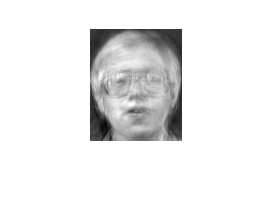

reconstructed_mat_img = (reconstructed_mat_img - min(reconstructed_mat_img, [], 'all')) / (max(reconstructed_mat_img, [], 'all') - min(reconstructed_mat_img, [], 'all'));
imshow(reconstructed_mat_img)

imwrite(reconstructed_mat_img, "Q8rec.bmp")
%Q9
%reconstruction using 120 eigenfaces
eig_120_face = U(:, 1:120)

eig_120_face = 10304×120
    0.0069    0.0165    0.0177    0.0039    0.0065   -0.0063   -0.0080    0.0072   -0.0017    0.0018    0.0063    0.0078    0.0081   -0.0089    0.0004    0.0025    0.0007    0.0038   -0.0015    0.0091   -0.0112    0.0102   -0.0019    0.0036   -0.0100   -0.0073   -0.0044    0.0039   -0.0076    0.0025
    0.0069    0.0165    0.0180    0.0038    0.0066   -0.0061   -0.0077    0.0071   -0.0018    0.0020    0.0059    0.0077    0.0072   -0.0093    0.0013    0.0028    0.0001    0.0028   -0.0009    0.0089   -0.0101    0.0104   -0.0015    0.0038   -0.0102   -0.0072   -0.0048    0.0031   -0.0080    0.0023
    0.0069    0.0164    0.0177    0.0040    0.0065   -0.0056   -0.0079    0.0068   -0.0017    0.0025    0.0059    0.0076    0.0070   -0.0087    0.0006    0.0026    0.0004    0.0031   -0.0011    0.0089   -0.0103    0.0107   -0.0015    0.0036   -0.0088   -0.0074   -0.0027    0.0043   -0.0073    0.0026
    0.0069    0.0164    0.0178    0.0040    0.0067   -0.0056   -0.0077  

eig_120_face_t = eig_120_face'

eig_120_face_t = 120×10304
    0.0069    0.0069    0.0069    0.0069    0.0066    0.0065    0.0066    0.0066    0.0067    0.0067    0.0067    0.0069    0.0069    0.0075    0.0078    0.0078    0.0080    0.0083    0.0087    0.0090    0.0094    0.0091    0.0087    0.0081    0.0077    0.0072    0.0070    0.0069    0.0072    0.0068
    0.0165    0.0165    0.0164    0.0164    0.0164    0.0162    0.0161    0.0162    0.0160    0.0158    0.0155    0.0146    0.0142    0.0138    0.0135    0.0130    0.0128    0.0123    0.0119    0.0116    0.0109    0.0101    0.0093    0.0087    0.0075    0.0064    0.0050    0.0037    0.0028    0.0021
    0.0177    0.0180    0.0177    0.0178    0.0177    0.0177    0.0175    0.0177    0.0175    0.0173    0.0176    0.0175    0.0179    0.0175    0.0173    0.0180    0.0179    0.0175    0.0166    0.0162    0.0158    0.0152    0.0148    0.0141    0.0137    0.0134    0.0123    0.0118    0.0110    0.0096
    0.0039    0.0038    0.0040    0.0040    0.0038    0.0043    0.0044

W_120 = eig_120_face_t*(image_mat-mean_mat)

W_120 = 120×1
1.0e+03 *

   -0.0104
   -1.4385
   -1.5962
   -0.3618
   -0.4327
   -0.1762
    0.6375
   -0.7229
    0.0123
    0.5631


reconstructed_mat_120 = (eig_120_face * W_120) + mean_mat

reconstructed_mat_120 = 10304×1
   38.4802
   39.7194
   40.8728
   40.4897
   40.0440
   42.9166
   36.6952
   35.5129
   40.3164
   37.9429


reconstructed_mat_img_120 = reshape(reconstructed_mat_120, [112, 92])

reconstructed_mat_img_120 = 112×92
   38.4802   39.0638   39.5521   37.0740   37.4581   36.6540   37.1055   36.5980   37.1056   32.7777   37.9481   35.5598   40.9724   41.6640   40.7794   42.4449   35.5691   37.5780   33.1871   38.0500   46.2798   48.5171   50.8006   45.5716   44.5046   39.0813   35.0014   36.2496   37.6457   32.7193
   39.7194   36.3552   41.6509   39.5657   38.9927   37.0102   38.0726   33.3257   33.8584   33.1388   40.4385   38.9220   42.8487   40.6057   39.3968   40.9337   36.6948   38.5014   42.6080   44.0453   49.1363   49.4721   45.4390   44.9222   49.6852   43.9297   42.8116   40.0595   39.5621   30.1647
   40.8728   38.2417   38.2896   39.5069   38.1728   39.5741   32.2216   33.0413   40.7899   40.4882   35.5836   41.5810   40.5383   41.4583   35.4207   41.4195   39.9428   40.1855   44.2960   45.0282   41.3876   44.3789   49.4884   55.2140   58.8982   62.2547   51.0410   44.4827   38.7755   30.7393
   40.4897   39.5454   38.2843   39.9755   38.1737   33.4496  

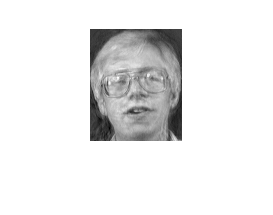

reconstructed_mat_img_120 = (reconstructed_mat_img_120 - min(reconstructed_mat_img_120, [], 'all')) / (max(reconstructed_mat_img_120, [], 'all') - min(reconstructed_mat_img_120, [], 'all'));
imshow(reconstructed_mat_img_120)

imwrite(reconstructed_mat_img_120,"Q9rec.bmp")